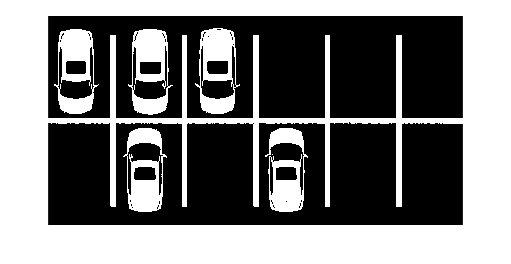

clc;clear;close all;
image = imread('filled5.png');
mask = imread('mask.png');
I=imbinarize(im2gray(image));
I2=imbinarize(im2gray(mask));
image = im2double(image);
mask = im2double(mask);
imshow(I)

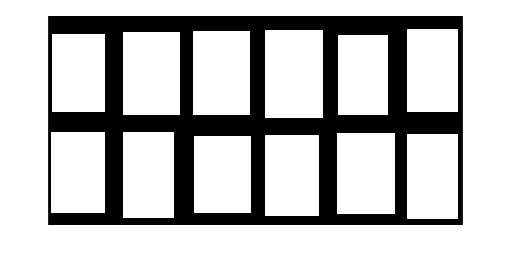

imshow(I2)

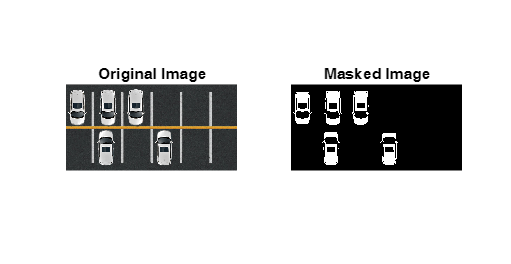


maskedImage = I .* I2;
imwrite(maskedImage,"MaskedImage2.png")

subplot(1, 2, 1);
imshow(image);
title('Original Image');

subplot(1, 2, 2);
imshow(maskedImage);
title('Masked Image');